clc; clear;

Enter Time axis as [start:step:stop]:

t = -5:0.1:5;

Enter the axis values as [d1 d2 ... dk] where the signal changes its shape/waveform:

disconts = [0 2 4];

Enter signal shape/waveform sections:

section_1 = 0*t;
section_2 = sin(pi*(t)./2);
section_3 =-sin(pi*(t)./2);
section_4 = 0*t;
sections = [section_1; section_2; section_3; section_4];

[a_signal, a_str] = AperiodicSignal(AxisType.t,t,disconts,sections);
fprintf("%s",compose("signal shape/waveform sections :\n%s", a_str));

signal shape/waveform sections :
  t<0 , section_1
  0<=t<2 , section_2
  2<=t<4 , section_3
  t=>4 , section_4


%Draw(AxisType.t,t,a_signal)

[b_signal, str_b] = AperiodicSignal(AxisType.t,t, [0 1], [zeros(size(t)); 3*ones(size(t)); zeros(size(t))]);
fprintf("%s",compose("signal shape/waveform sections :\n%s", str_b));

signal shape/waveform sections :
  t<0 , section_1
  0<=t<1 , section_2
  t=>1 , section_3


b_signal(-t)

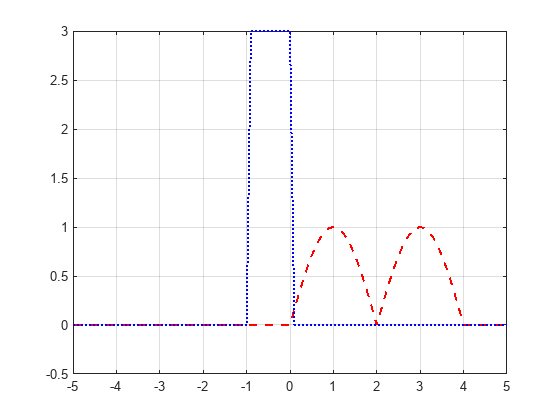

br_signal = Reflect(b_signal);
plot(t,a_signal,'--r','linewidth',1.5)
hold on, grid on
plot(t,br_signal,':b','linewidth',1.5)
hold off

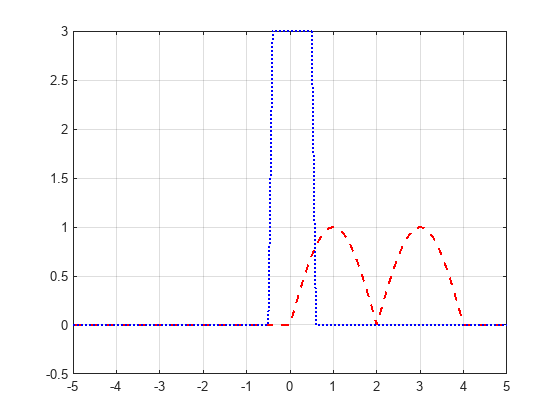

plot(t,a_signal,'--r','linewidth',1.5)
hold on, grid on
plot(t,Shift(t,br_signal,-0.5),':b','linewidth',1.5)
hold off

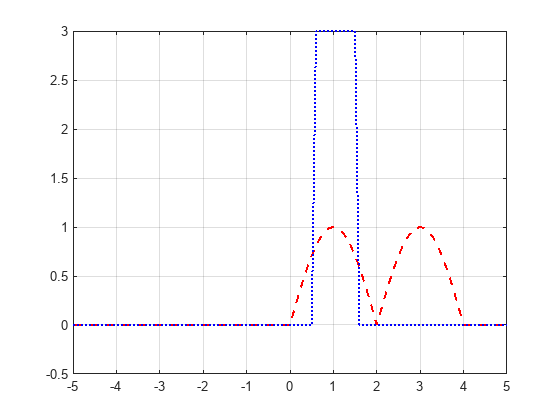

plot(t,a_signal,'--r','linewidth',1.5)
hold on, grid on
plot(t,Shift(t,br_signal,-1.5),':b','linewidth',1.5)
hold off

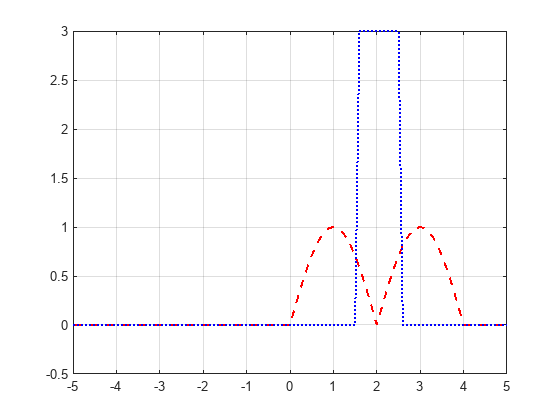

plot(t,a_signal,'--r','linewidth',1.5)
hold on, grid on
plot(t,Shift(t,br_signal,-2.5),':b','linewidth',1.5)
hold off

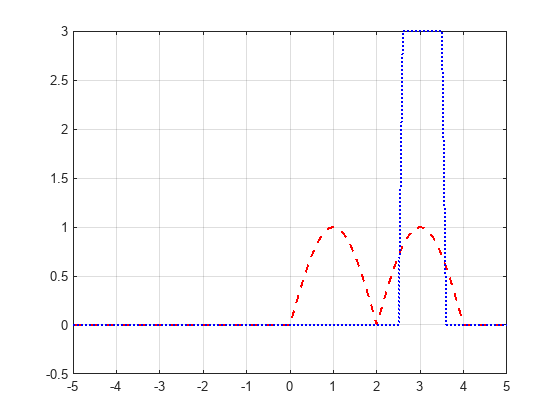

plot(t,a_signal,'--r','linewidth',1.5)
hold on, grid on
plot(t,Shift(t,br_signal,-3.5),':b','linewidth',1.5)
hold off

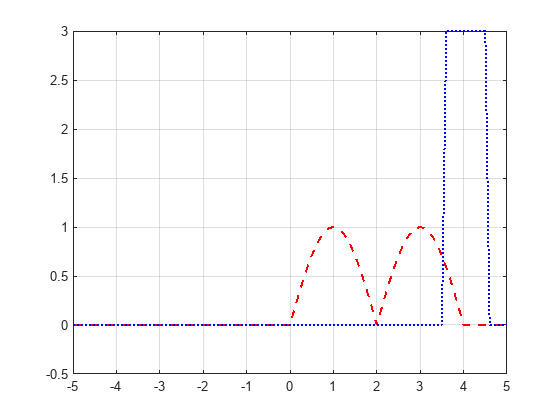

plot(t,a_signal,'--r','linewidth',1.5)
hold on, grid on
plot(t,Shift(t,br_signal,-4.5),':b','linewidth',1.5)
hold off

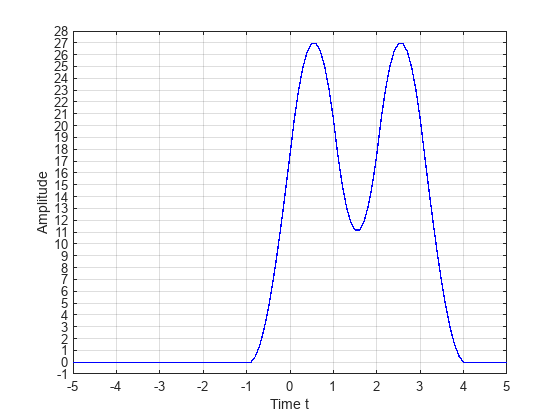

Draw(AxisType.t,t,conv(a_signal,br_signal,"same"))

Draw(AxisType.t,t, Convolve(a_signal,br_signal,ConvType.Same))

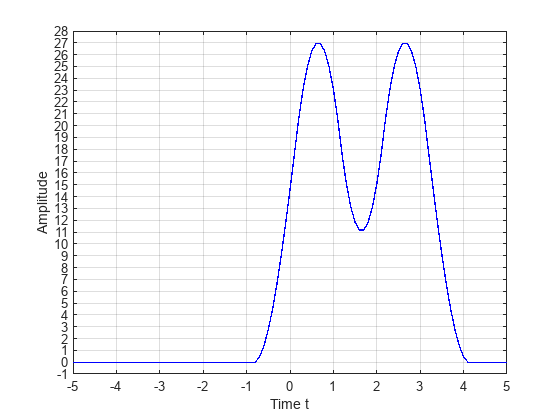

Draw(AxisType.t,t, Convolve(a_signal,br_signal,ConvType.Right))